clear;
clc;

A

A = eye(8);
A(1,4) = 1;
A(2,5) = 1;
A(3,6) = 1;
A(4,7) = 9.81;
A(5,8) = 9.81;

disp(A)

    1.0000         0         0    1.0000         0         0         0         0
         0    1.0000         0         0    1.0000         0         0         0
         0         0    1.0000         0         0    1.0000         0         0
         0         0         0    1.0000         0         0    9.8100         0
         0         0         0         0    1.0000         0         0    9.8100
         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0    1.0000



B

B = zeros(8,3);
B(6,1) = 1;
B(7,2) = 1;
B(8,3) = 1;
disp(B)

     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     0     0     1



Q

Q = diag([100, 100, 100, 10, 10, 10, 1, 1]);
disp(Q)

   100     0     0     0     0     0     0     0
     0   100     0     0     0     0     0     0
     0     0   100     0     0     0     0     0
     0     0     0    10     0     0     0     0
     0     0     0     0    10     0     0     0
     0     0     0     0     0    10     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1



R

R = eye(3)*0.1;
disp(R)

    0.1000         0         0
         0    0.1000         0
         0         0    0.1000



P

[P,K,L] = idare(A,B,Q,R,[],[])

P = 	1.0e+04 *

    0.0309    0.0000   -0.0000    0.0318    0.0000   -0.0000    0.1071    0.0000
    0.0000    0.0309   -0.0000    0.0000    0.0318   -0.0000    0.0000    0.1071
   -0.0000   -0.0000    0.0209   -0.0000   -0.0000    0.0109   -0.0000   -0.0000
    0.0318    0.0000   -0.0000    0.0557    0.0000   -0.0000    0.2241    0.0000
    0.0000    0.0318   -0.0000    0.0000    0.0557   -0.0000    0.0000    0.2241
   -0.0000   -0.0000    0.0109   -0.0000   -0.0000    0.0120   -0.0000   -0.0000
    0.1071    0.0000   -0.0000    0.2241    0.0000   -0.0000    1.1475   -0.0000
    0.0000    0.1071   -0.0000    0.0000    0.2241   -0.0000   -0.0000    1.1475


K =    -0.0000   -0.0000    0.9140   -0.0000   -0.0000    1.9132   -0.0000   -0.0000
    0.0934    0.0000   -0.0000    0.2886    0.0000   -0.0000    2.9157   -0.0000
    0.0000    0.0934    0.0000    0.0000    0.2886    0.0000    0.0000    2.9157


L =    0.0839 + 0.0000i
   0.0839 + 0.0000i
   0.0758 + 0.0000i
   0.0110 + 0.0000i
   0.0002 + 0.0102i
   0.0002 - 0.0102i
   0.0002 + 0.0102i
   0.0002 - 0.0102i


disp(round(P))

         309           0           0         318           0           0        1071           0
           0         309           0           0         318           0           0        1071
           0           0         209           0           0         109           0           0
         318           0           0         557           0           0        2241           0
           0         318           0           0         557           0           0        2241
           0           0         109           0           0         120           0           0
        1071           0           0        2241           0           0       11475           0
           0        1071           0           0        2241           0           0       11475



M = csvread('N.csv');
M2 = csvread('Q_100.csv');
M3 = csvread('Q_10.csv');
M4 = csvread('Q_1.csv');
M5 = csvread('Q_01.csv');
M6 = csvread('Q_001.csv');

quad_obs = M(:,1:9)

quad_obs =    -0.3000         0    0.0002    0.0000    0.0600    0.0000         0         0    0.0151
   -0.2999   -0.0000    0.0006    0.0000    0.1199    0.0000    0.0125   -0.0000    0.0268
   -0.2994   -0.0000    0.0012    0.0000    0.1799    0.0000    0.0368   -0.0000    0.0325
   -0.2983   -0.0000    0.0018    0.0000    0.2398    0.0000    0.0721   -0.0000    0.0306
   -0.2964   -0.0000    0.0023    0.0000    0.2995    0.0000    0.1174   -0.0000    0.0196
   -0.2935   -0.0000    0.0025    0.0000    0.3355    0.0000    0.1715   -0.0000   -0.0015
   -0.2895   -0.0000    0.0021    0.0000    0.3516    0.0000    0.2293   -0.0000   -0.0319
   -0.2843   -0.0000    0.0011    0.0000    0.3520    0.0000    0.2870   -0.0000   -0.0707
   -0.2780   -0.0000   -0.0008    0.0000    0.3403    0.0000    0.3420   -0.0000   -0.1173
   -0.2707   -0.0000   -0.0037    0.0000    0.3196    0.0000    0.3923   -0.0000   -0.1715


quad_act = M(:,10:13)

quad_act =    10.5675    0.0000    3.0000         0
   10.4098    0.0000    3.0000         0
   10.1712    0.0000    3.0000         0
    9.8724    0.0000    3.0000         0
    9.5314    0.0000    2.9942         0
    9.1634    0.0000    1.8020         0
    8.7810    0.0000    0.8074         0
    8.3830    0.0000    0.0189         0
    7.9674    0.0000   -0.5869         0
    7.5336    0.0000   -1.0348         0


pend_obs = M(:,14:22)

pend_obs =          0         0   -0.4420         0         0         0         0         0   -2.8038
         0         0   -0.3878         0         0         0         0         0   -2.6076
         0         0   -0.3377         0         0         0         0         0   -2.4114
         0         0   -0.2914         0         0         0         0         0   -2.2152
         0         0   -0.2490         0         0         0         0         0   -2.0190
         0         0   -0.2106         0         0         0         0         0   -1.8228
         0         0   -0.1761         0         0         0         0         0   -1.6266
         0         0   -0.1456         0         0         0         0         0   -1.4304
         0         0   -0.1189         0         0         0         0         0   -1.2342
         0         0   -0.0962         0         0         0         0         0   -1.0380


quad_s0 = M(:,23:30)

quad_s0 =    -0.3000         0    0.5000         0         0   -3.0000         0         0
   -0.3000         0    0.4421         0         0   -2.7887    0.0000    0.0600
   -0.2999   -0.0000    0.3884    0.0125   -0.0000   -2.5808    0.0000    0.1199
   -0.2994   -0.0000    0.3388    0.0368   -0.0000   -2.3789    0.0000    0.1799
   -0.2983   -0.0000    0.2932    0.0721   -0.0000   -2.1846    0.0000    0.2398
   -0.2964   -0.0000    0.2513    0.1174   -0.0000   -1.9994    0.0000    0.2995
   -0.2935   -0.0000    0.2131    0.1715   -0.0000   -1.8243    0.0000    0.3355
   -0.2895   -0.0000    0.1783    0.2293   -0.0000   -1.6585    0.0000    0.3516
   -0.2843   -0.0000    0.1467    0.2870   -0.0000   -1.5011    0.0000    0.3520
   -0.2780   -0.0000    0.1182    0.3420   -0.0000   -1.3515    0.0000    0.3403


t = M(:,31)

t =     0.0200
    0.2280
    0.3850
    0.5360
    0.6910
    0.8490
    1.0010
    1.1620
    1.3160
    1.4700


cost = M(:,32)

cost =   133.3100
  118.4500
  104.9820
   92.6653
   81.5532
   71.5813
   63.0131
   55.5642
   48.9955
   43.1320


stage_cost = M(:,33)

stage_cost =    23.0786
   20.1803
   17.6958
   15.5732
   13.7617
   11.9326
   10.4833
    9.3081
    8.3217
    7.4652


terminal_cost = M(:,34)

terminal_cost =    50.8330
   44.9513
   39.6115
   34.7696
   30.4097
   26.5403
   23.2889
   20.5208
   18.1242
   16.0162



[quad_obs_2,quad_act_2,pend_obs_2,quad_s0_2,t_2,cost_2,stage_cost_2,terminal_cost_2] = extract_raw(M2);
[quad_obs_3,quad_act_3,pend_obs_3,quad_s0_3,t_3,cost_3,stage_cost_3,terminal_cost_3] = extract_raw(M3);
[quad_obs_4,quad_act_4,pend_obs_4,quad_s0_4,t_4,cost_4,stage_cost_4,terminal_cost_4] = extract_raw(M4);
[quad_obs_5,quad_act_5,pend_obs_5,quad_s0_5,t_5,cost_5,stage_cost_5,terminal_cost_5] = extract_raw(M5);
[quad_obs_6,quad_act_6,pend_obs_6,quad_s0_6,t_6,cost_6,stage_cost_6,terminal_cost_6] = extract_raw(M6);

T = 1.5

T = 1.5000

t2 = linspace(0,T,size(quad_obs,1))

t2 =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


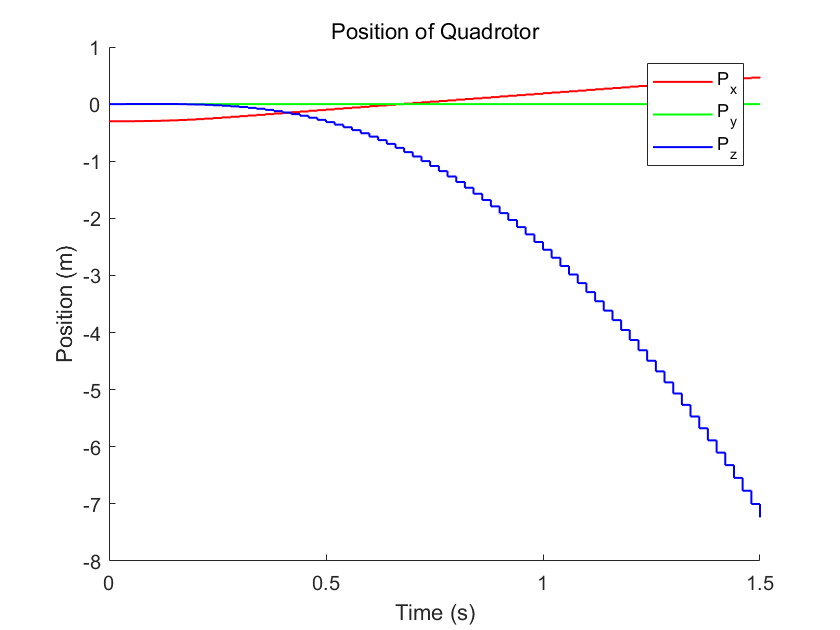

l_w = 1;
m_s = 20;

figure()
hold on
stairs(t2,quad_obs(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_obs(:,2),'g',"LineWidth",l_w)
stairs(t2,quad_obs(:,3),'b',"LineWidth",l_w)
hold off
title('Position of Quadrotor')
xlabel('Time (s)')
ylabel('Position (m)')
legend('P_x','P_y','P_z')

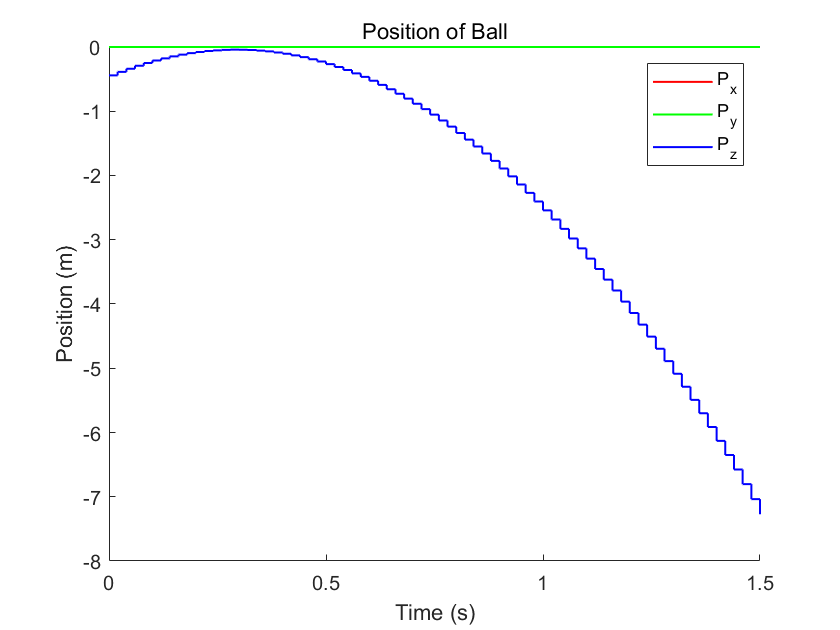


figure()
hold on
stairs(t2,pend_obs(:,1),'r',"LineWidth",l_w)
stairs(t2,pend_obs(:,2),'g',"LineWidth",l_w)
stairs(t2,pend_obs(:,3),'b',"LineWidth",l_w)
hold off
title('Position of Ball')
xlabel('Time (s)')
ylabel('Position (m)')
legend('P_x','P_y','P_z')

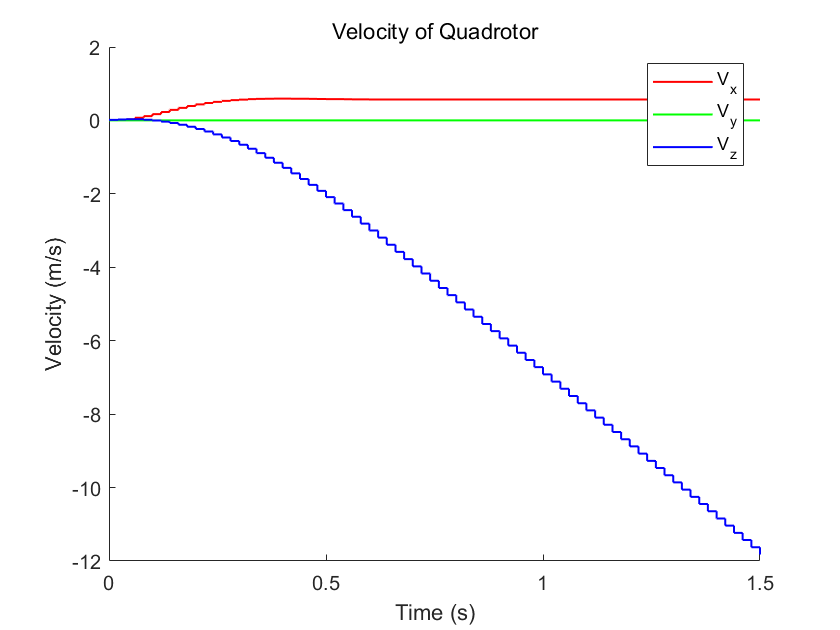

figure()
hold on
stairs(t2,quad_obs(:,7),'r',"LineWidth",l_w)
stairs(t2,quad_obs(:,8),'g',"LineWidth",l_w)
stairs(t2,quad_obs(:,9),'b',"LineWidth",l_w)
hold off
title('Velocity of Quadrotor')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('V_x','V_y','V_z')

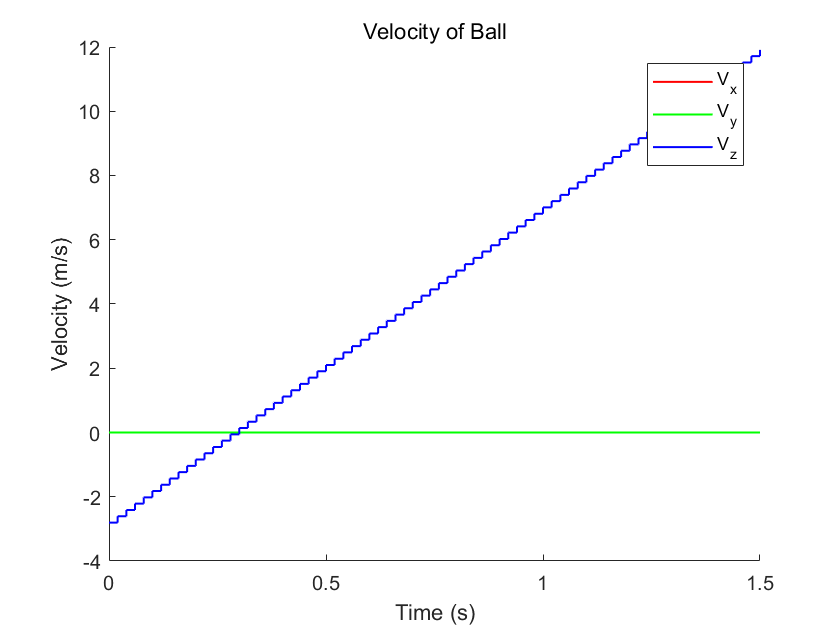


figure()
hold on
stairs(t2,pend_obs(:,7),'r',"LineWidth",l_w)
stairs(t2,pend_obs(:,8),'g',"LineWidth",l_w)
stairs(t2,pend_obs(:,9),'b',"LineWidth",l_w)
hold off
title('Velocity of Ball')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('V_x','V_y','V_z')

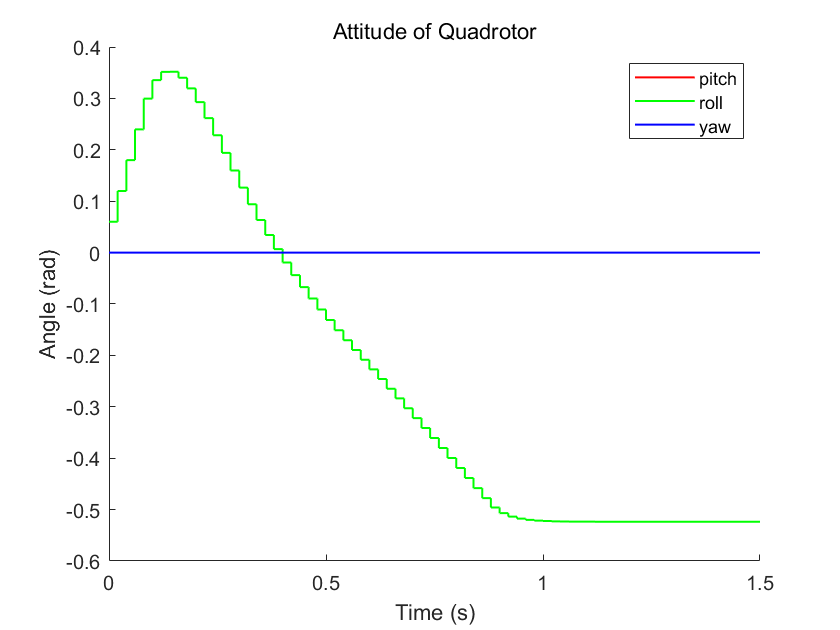

figure()
hold on
stairs(t2,quad_obs(:,4),'r',"LineWidth",l_w)
stairs(t2,quad_obs(:,5),'g',"LineWidth",l_w)
stairs(t2,quad_obs(:,6),'b',"LineWidth",l_w)
hold off
title('Attitude of Quadrotor')
xlabel('Time (s)')
ylabel('Angle (rad)')
legend('pitch','roll','yaw')

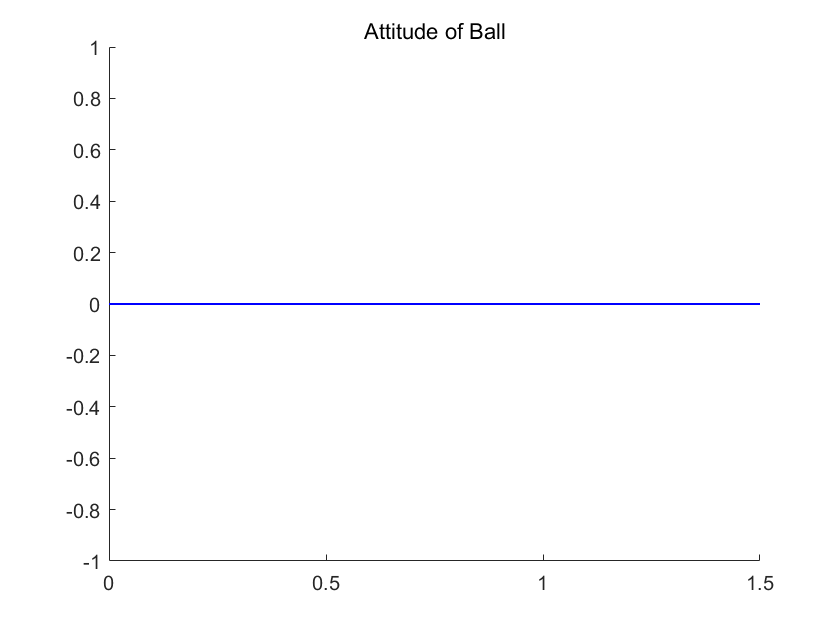


figure()
hold on
stairs(t2,pend_obs(:,4),'r',"LineWidth",l_w)
stairs(t2,pend_obs(:,5),'g',"LineWidth",l_w)
stairs(t2,pend_obs(:,6),'b',"LineWidth",l_w)
hold off
title('Attitude of Ball')

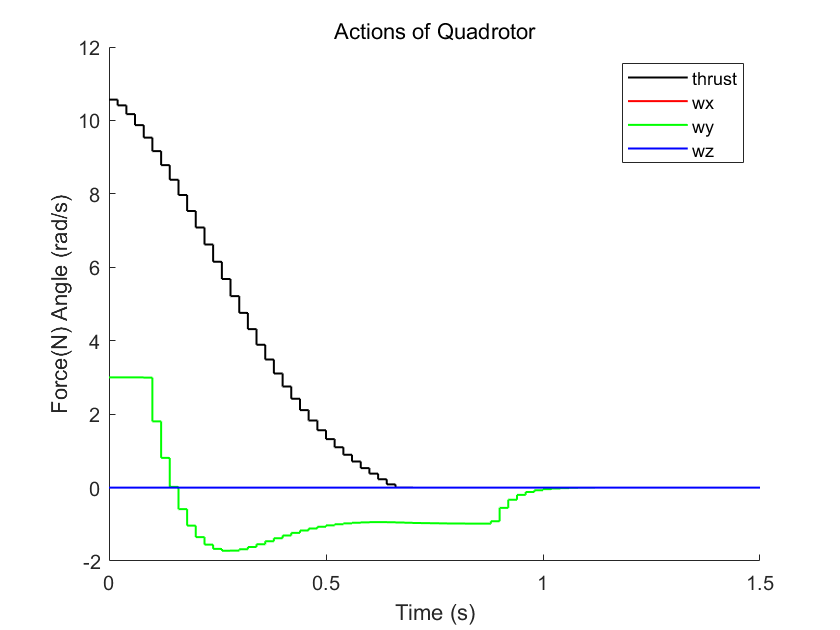

figure()
hold on
stairs(t2,quad_act(:,1),'k',"LineWidth",l_w)
stairs(t2,quad_act(:,2),'r',"LineWidth",l_w)
stairs(t2,quad_act(:,3),'g',"LineWidth",l_w)
stairs(t2,quad_act(:,4),'b',"LineWidth",l_w)
hold off
title('Actions of Quadrotor')
xlabel('Time (s)')
ylabel('Force(N) Angle (rad/s)')
legend('thrust','wx','wy','wz')

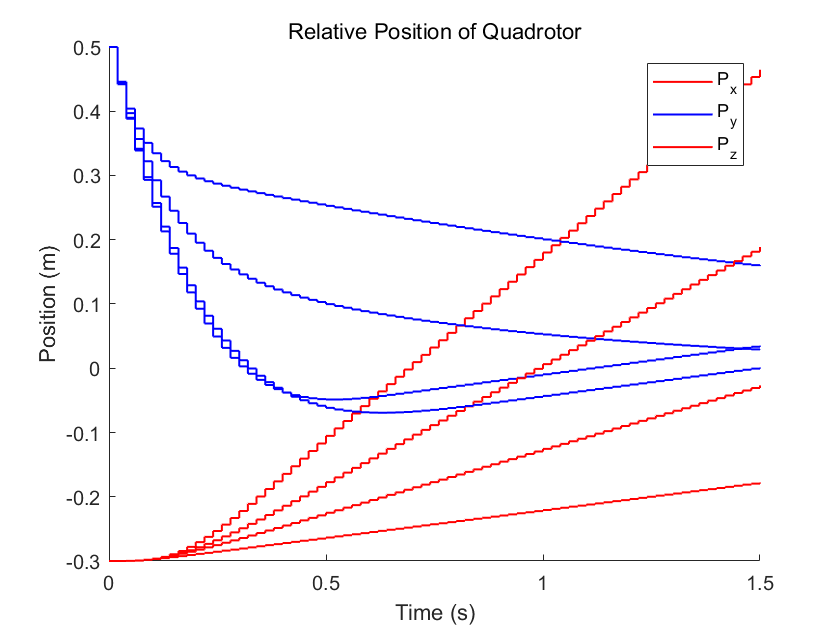

figure()
hold on
stairs(t2,quad_s0(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_s0(:,3),'b',"LineWidth",l_w)
stairs(t2,quad_s0_2(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_s0_2(:,3),'b',"LineWidth",l_w)
stairs(t2,quad_s0_3(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_s0_3(:,3),'b',"LineWidth",l_w)
stairs(t2,quad_s0_4(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_s0_4(:,3),'b',"LineWidth",l_w)
hold off
title('Relative Position of Quadrotor')
xlabel('Time (s)')
ylabel('Position (m)')
legend('P_x','P_y','P_z')

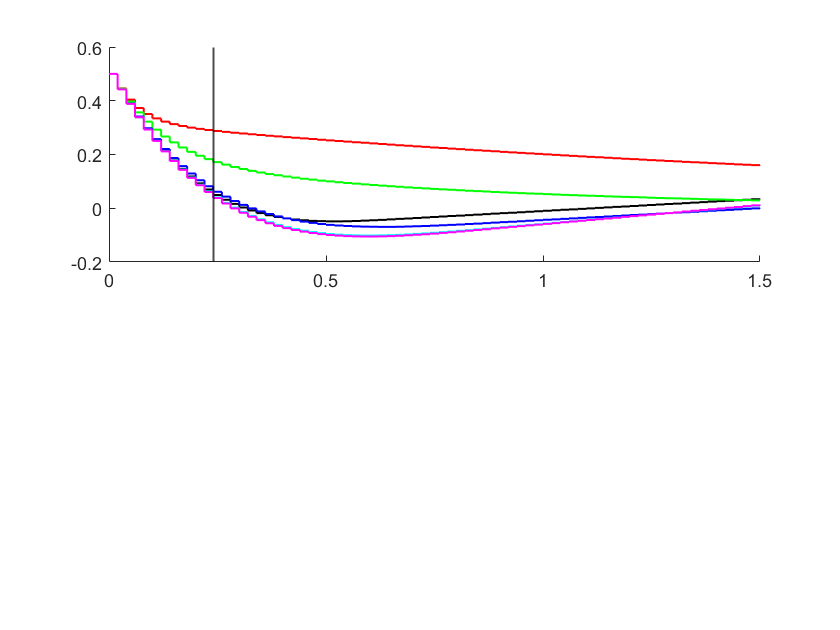


% figure()
% subplot(211)
% hold on
% stairs(t2,quad_s0(:,3),'k',"LineWidth",l_w)
% stairs(t2,quad_s0_2(:,3),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,3),'g',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,3),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_5(:,3),'c',"LineWidth",l_w)
% stairs(t2,quad_s0_6(:,3),'m',"LineWidth",l_w)
% a_idx = abs(quad_s0(:,3))<=0.05;
% a = t2(a_idx);
% xline(a(1),'k',"LineWidth",l_w)

% %scatter(t2(a_idx),quad_s0(a_idx),15,'ko','filled','LineWidth',0.1)
% b = t2(abs(quad_s0_2(:,3))<=0.1)


b =

  空的 1×0 double 行向量



% xline(b(1),'r',"LineWidth",l_w)

索引超出数组元素的数目(0)。

% c = t2(abs(quad_s0_3(:,3))<=0.1)
% xline(c(1),'g',"LineWidth",l_w)
% d = t2(abs(quad_s0_4(:,3))<=0.1)
% xline(d(1),'b',"LineWidth",l_w)
% e = t2(abs(quad_s0_5(:,3))<=0.1)
% xline(e(1),'c',"LineWidth",l_w)
% f = t2(abs(quad_s0_6(:,3))<=0.1)
% xline(f(1),'m',"LineWidth",l_w)
% title('Relative Position of Quadrotor')
% yline(0)
% ylabel('P_z (m)')
% hold off
% subplot(212)
% hold on
% stairs(t2,quad_s0(:,1),'k',"LineWidth",l_w)
% stairs(t2,quad_s0_2(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,1),'g',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,1),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_5(:,1),'c',"LineWidth",l_w)
% stairs(t2,quad_s0_6(:,1),'m',"LineWidth",l_w)
% xline(a(1),'k',"LineWidth",l_w)
% xline(b(1),'r',"LineWidth",l_w)
% xline(c(1),'g',"LineWidth",l_w)
% xline(d(1),'b',"LineWidth",l_w)
% xline(e(1),'c',"LineWidth",l_w)
% xline(f(1),'m',"LineWidth",l_w)
% yline(-0.05)
% yline(0.05)
% ylim([-0.5 0.5])
% scatter(t2(a_idx),quad_s0(a_idx),15,'ko','filled','LineWidth',0.1)
% scatter(t2(abs(quad_s0_5(:,3))<=0.05),quad_s0_5(abs(quad_s0_5(:,3))<=0.05),15,'co','filled','LineWidth',0.1)
% scatter(t2(abs(quad_s0_6(:,3))<=0.06),quad_s0_6(abs(quad_s0_6(:,3))<=0.06),15,'mo','filled','LineWidth',0.1)
% hold off
% xlabel('Time (s)')
% ylabel('P_x (m)')
% legend('Q=default','Q=100I','Q=10I','Q=1I','Q=0.1I','Q=0.01I')

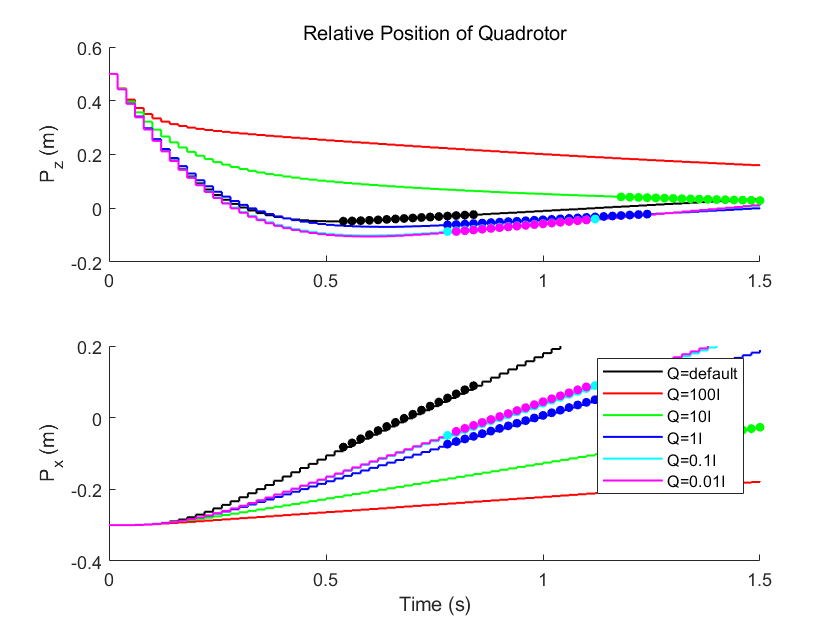

% Best
figure()
subplot(211)
hold on
stairs(t2,quad_s0(:,3),'k',"LineWidth",l_w)
stairs(t2,quad_s0_2(:,3),'r',"LineWidth",l_w)
stairs(t2,quad_s0_3(:,3),'g',"LineWidth",l_w)
stairs(t2,quad_s0_4(:,3),'b',"LineWidth",l_w)
stairs(t2,quad_s0_5(:,3),'c',"LineWidth",l_w)
stairs(t2,quad_s0_6(:,3),'m',"LineWidth",l_w)
a =  sqrt(sum(quad_s0(:,1:3).^2,2))<=0.1;
b = sqrt(sum(quad_s0_2(:,1:3).^2,2))<=0.1;
c = sqrt(sum(quad_s0_3(:,1:3).^2,2))<=0.1;
d = sqrt(sum(quad_s0_4(:,1:3).^2,2))<=0.1;
e = sqrt(sum(quad_s0_5(:,1:3).^2,2))<=0.1;
f = sqrt(sum(quad_s0_6(:,1:3).^2,2))<=0.1;
scatter(t2(a),quad_s0(a,3),m_s,'ko','filled','LineWidth',0.1)
scatter(t2(b),quad_s0_2(b,3),m_s,'ro','filled','LineWidth',0.1)
scatter(t2(c),quad_s0_3(c,3),m_s,'go','filled','LineWidth',0.1)
scatter(t2(d),quad_s0_4(d,3),m_s,'bo','filled','LineWidth',0.1)
scatter(t2(e),quad_s0_5(e,3),m_s,'co','filled','LineWidth',0.1)
scatter(t2(f),quad_s0_6(f,3),m_s,'mo','filled','LineWidth',0.1)
title('Relative Position of Quadrotor')
ylabel('P_z (m)')
hold off
subplot(212)
hold on
stairs(t2,quad_s0(:,1),'k',"LineWidth",l_w)
stairs(t2,quad_s0_2(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_s0_3(:,1),'g',"LineWidth",l_w)
stairs(t2,quad_s0_4(:,1),'b',"LineWidth",l_w)
stairs(t2,quad_s0_5(:,1),'c',"LineWidth",l_w)
stairs(t2,quad_s0_6(:,1),'m',"LineWidth",l_w)
scatter(t2(a),quad_s0(a,1),m_s,'ko','filled','LineWidth',0.1)
scatter(t2(b),quad_s0_2(b,1),m_s,'ro','filled','LineWidth',0.1)
scatter(t2(c),quad_s0_3(c,1),m_s,'go','filled','LineWidth',0.1)
scatter(t2(d),quad_s0_4(d,1),m_s,'bo','filled','LineWidth',0.1)
scatter(t2(e),quad_s0_5(e,1),m_s,'co','filled','LineWidth',0.1)
scatter(t2(f),quad_s0_6(f,1),m_s,'mo','filled','LineWidth',0.1)
ylim([-0.4 0.2])
hold off
xlabel('Time (s)')
ylabel('P_x (m)')
legend('Q=default','Q=100I','Q=10I','Q=1I','Q=0.1I','Q=0.01I')

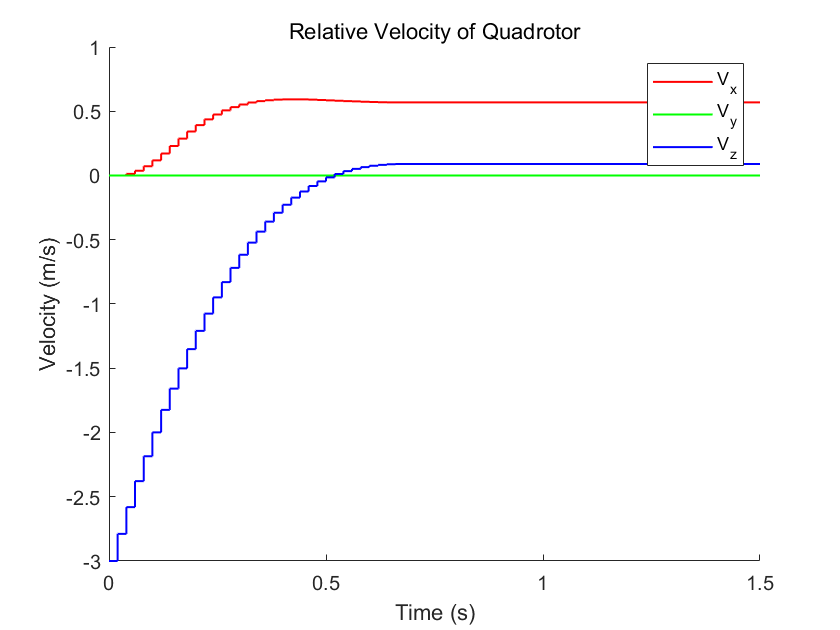

figure()
hold on
stairs(t2,quad_s0(:,4),'r',"LineWidth",l_w)
stairs(t2,quad_s0(:,5),'g',"LineWidth",l_w)
stairs(t2,quad_s0(:,6),'b',"LineWidth",l_w)
hold off
title('Relative Velocity of Quadrotor')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('V_x','V_y','V_z')

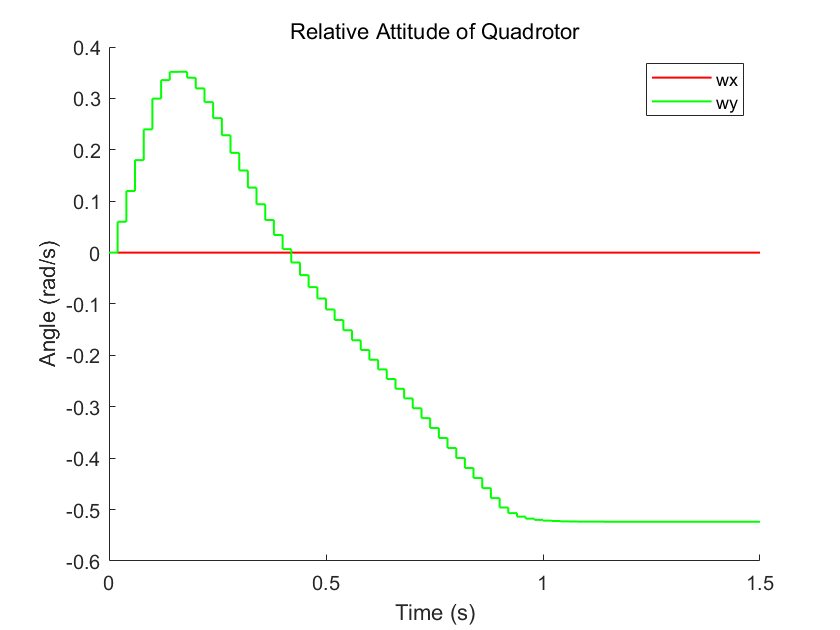


figure()
hold on
stairs(t2,quad_s0(:,7),'r',"LineWidth",l_w)
stairs(t2,quad_s0(:,8),'g',"LineWidth",l_w)
hold off
title('Relative Attitude of Quadrotor')
xlabel('Time (s)')
ylabel('Angle (rad/s)')
legend('wx','wy')

a = terminal_cost(2:size(terminal_cost,1));
b = terminal_cost(1:(size(terminal_cost,1)-1));
terminal_cost_diff = a-b;

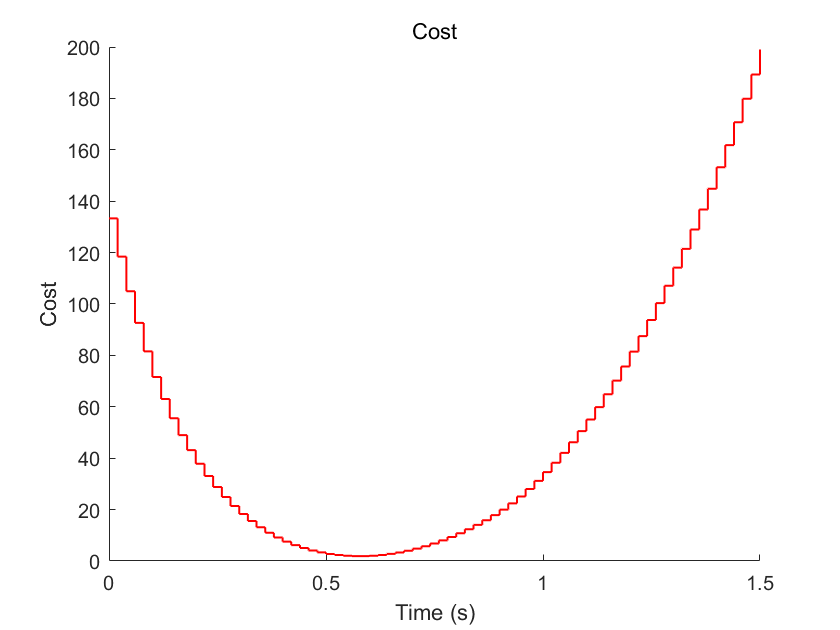

figure()
hold on
stairs(t2,cost,'r',"LineWidth",l_w)
hold off
title('Cost')
xlabel('Time (s)')
ylabel('Cost')

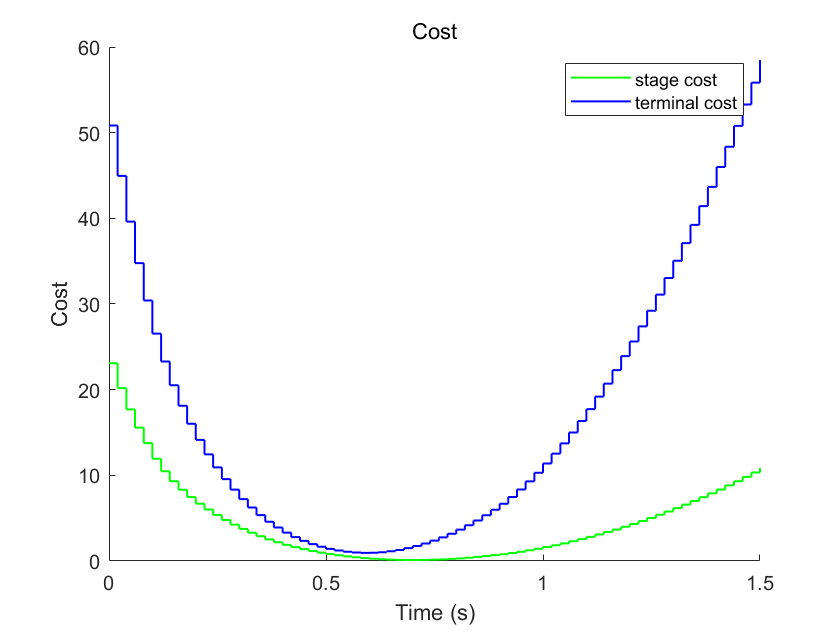


figure()
hold on
stairs(t2,stage_cost,'g',"LineWidth",l_w)
stairs(t2,terminal_cost,'b',"LineWidth",l_w)
hold off
title('Cost')
xlabel('Time (s)')
ylabel('Cost')
legend('stage cost','terminal cost')

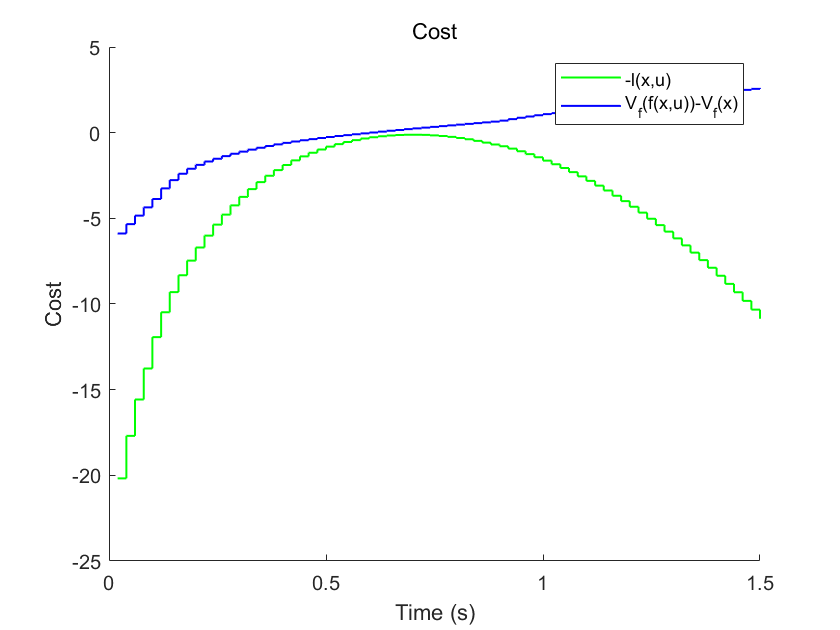


figure()
hold on
stairs(t2(2:size(terminal_cost,1)),-stage_cost(2:size(terminal_cost,1)),'g',"LineWidth",l_w)
stairs(t2(2:size(terminal_cost,1)),terminal_cost_diff,'b',"LineWidth",l_w)
hold off
title('Cost')
xlabel('Time (s)')
ylabel('Cost')
legend('-l(x,u)','V_f(f(x,u))-V_f(x)')